# [Solution] Iterative diagonalization

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Non-interacting tight-binding chain

The results for both chain types can be obtained within a single code block, by making a for-loop.

22-09-12 19:49:13 | #01/50 : NK=2/2
22-09-12 19:49:13 | #02/50 : NK=4/4
22-09-12 19:49:13 | #03/50 : NK=8/8
22-09-12 19:49:13 | #04/50 : NK=16/16
22-09-12 19:49:13 | #05/50 : NK=32/32
22-09-12 19:49:13 | #06/50 : NK=64/64
22-09-12 19:49:13 | #07/50 : NK=128/128
22-09-12 19:49:13 | #08/50 : NK=256/256
22-09-12 19:49:13 | #09/50 : NK=302/512
22-09-12 19:49:13 | #10/50 : NK=300/604
22-09-12 19:49:13 | #11/50 : NK=300/600
22-09-12 19:49:13 | #12/50 : NK=300/600
22-09-12 19:49:13 | #13/50 : NK=300/600
22-09-12 19:49:13 | #14/50 : NK=300/600
22-09-12 19:49:13 | #15/50 : NK=300/600
22-09-12 19:49:13 | #16/50 : NK=300/600
22-09-12 19:49:13 | #17/50 : NK=300/600
22-09-12 19:49:13 | #18/50 : NK=301/600
22-09-12 19:49:13 | #19/50 : NK=300/602
22-09-12 19:49:13 | #20/50 : NK=301/600
22-09-12 19:49:13 | #21/50 : NK=300/602
22-09-12 19:49:13 | #22/50 : NK=300/600
22-09-12 19:49:13 | #23/50 : NK=300/600
22-09-12 19:49:13 | #24/50 : NK=300/600
22-09-12 19:49:13 | #25/50 : NK=300/600
22-09-12 19:49:13 

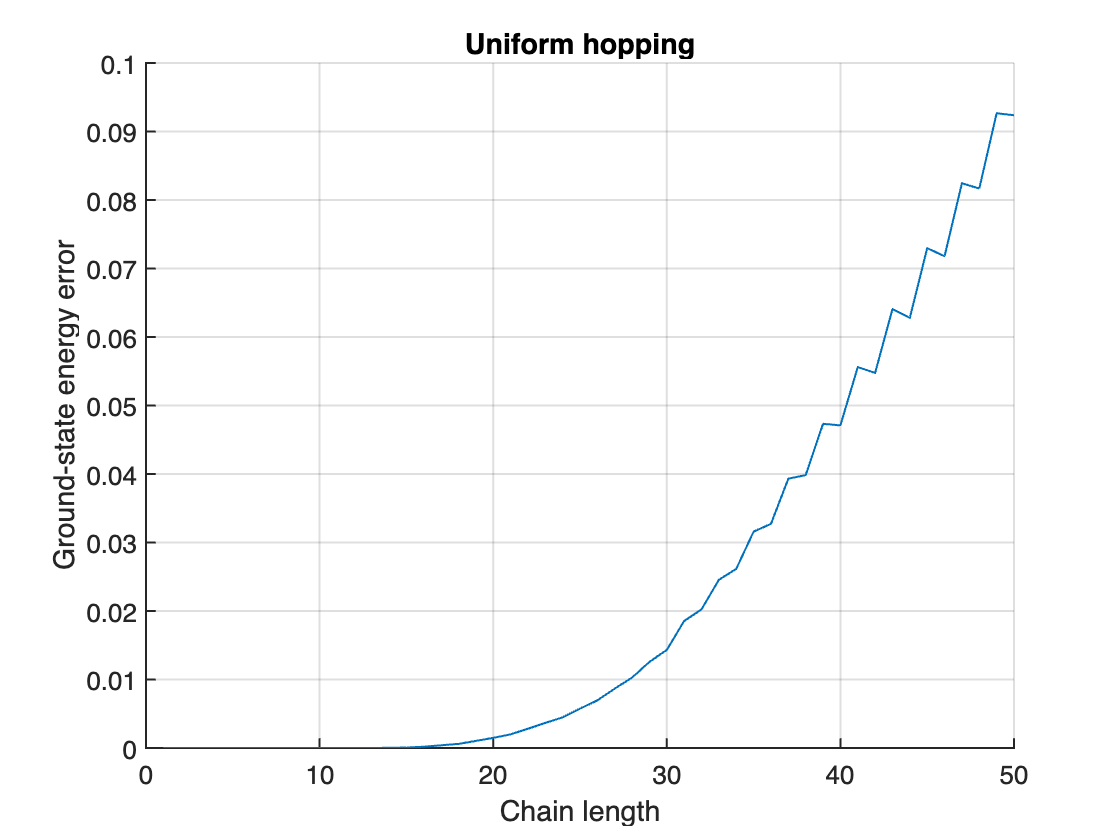

22-09-12 19:49:14 | #01/50 : NK=2/2
22-09-12 19:49:14 | #02/50 : NK=4/4
22-09-12 19:49:14 | #03/50 : NK=8/8
22-09-12 19:49:14 | #04/50 : NK=16/16
22-09-12 19:49:14 | #05/50 : NK=32/32
22-09-12 19:49:14 | #06/50 : NK=64/64
22-09-12 19:49:14 | #07/50 : NK=128/128
22-09-12 19:49:14 | #08/50 : NK=256/256
22-09-12 19:49:14 | #09/50 : NK=300/512
22-09-12 19:49:14 | #10/50 : NK=305/600
22-09-12 19:49:14 | #11/50 : NK=300/610
22-09-12 19:49:14 | #12/50 : NK=300/600
22-09-12 19:49:15 | #13/50 : NK=300/600
22-09-12 19:49:15 | #14/50 : NK=300/600
22-09-12 19:49:15 | #15/50 : NK=300/600
22-09-12 19:49:15 | #16/50 : NK=300/600
22-09-12 19:49:15 | #17/50 : NK=300/600
22-09-12 19:49:15 | #18/50 : NK=300/600
22-09-12 19:49:15 | #19/50 : NK=300/600
22-09-12 19:49:15 | #20/50 : NK=300/600
22-09-12 19:49:15 | #21/50 : NK=300/600
22-09-12 19:49:15 | #22/50 : NK=300/600
22-09-12 19:49:15 | #23/50 : NK=300/600
22-09-12 19:49:15 | #24/50 : NK=300/600
22-09-12 19:49:15 | #25/50 : NK=300/600
22-09-12 19:49:15 

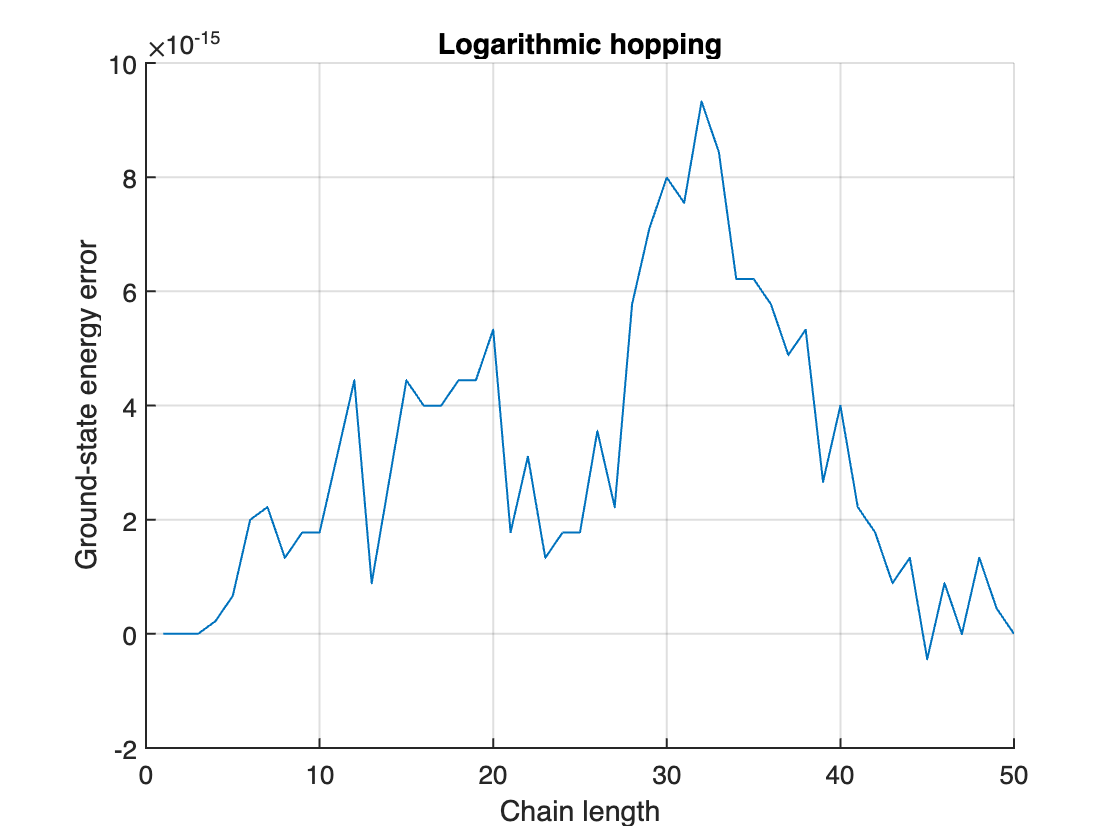

clear

N = 50; % maximum chain length

ts = {ones(1,N-1), ... % uniform hopping
      2.^(-(0:N-2)/2)}; % logarithmic hopping

% titles for plots; see below
strs = {'Uniform hopping', ...
        'Logarithmic hopping'};

Nkeep = 300;
tol = Nkeep*100*eps; % numerical tolerance for degeneracy

[F,Z,I] = getLocalSpace('Fermion');

for itE = (1:numel(ts))
    % tensors for the vaccum (i.e., dummy leg)
    Hprev = 0; % initialize Hamiltonian
    Aprev = 1; % identity tensor for the dummy leg
    
    % ground-state energies for different lengths
    E0_iter = zeros(1,N); % iterative diagonalization result
    E0_exact = zeros(1,N); % single-particle result
    
    for itN = (1:N)
        % add new site
        Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
        Hnow = updateLeft(Hprev,2,Anow,[],[],Anow);
        % update the Hamiltonian up to the last sites
        % to the enlarged Hilbert space
        
        if itN > 1
            % add hoping terms
            ZF = contract(Z,2,2,F,3,1);
            Hhop = (-ts{itE}(itN-1))*updateLeft(Fprev,3,Anow, ...
                permute(conj(ZF),[2 1 3]),3,Anow);
            % hopping from the last site to the current site
                
            Hnow = Hnow + Hhop + Hhop';
        end

        [V,D] = eig((Hnow+Hnow')/2);
        % sort eigenvalues and eigenvectors in the order of increasing
        % eigenvalues
        [D,ids] = sort(diag(D),'ascend');
        V = V(:,ids);
            
        E0_iter(itN) = D(1);
            
        % truncation threshold for energy
        Etr = D(min([numel(D);Nkeep]));
        oks = (D < (Etr + tol));
        % true: to keep, false: not to keep
        % keep all degenerate states up to tolerance
            
        Aprev = contract(Anow,3,2,V(:,oks),2,1,[1 3 2]);
        Hprev = diag(D(oks)); % vector -> diagonal matrix
        
        % update operator for the next iteration
        Fprev = updateLeft([],[],Aprev,F,3,Aprev);
        
        % exact solution by diagonalizing the single-particle Hamiltonian
        if itN > 1
            E0_exact(itN) = nonIntTB(ts{itE}(1:itN-1));
        end
    
        disptime(['#',sprintf('%02i/%02i',[itN,N]),' : ', ...
            'NK=',sprintf('%i/%i',[size(Aprev,2),size(Anow,2)])]);
    end
    figure;
    hold on;
    plot((1:N),E0_iter-E0_exact,'LineWidth',1,'LineStyle','-');
    hold off;
    set(gca,'LineWidth',1,'FontSize',13);
    xlabel('Chain length');
    ylabel('Ground-state energy error');
    grid on;
    title(strs{itE});
end

We find that iterative diagonalization results for uniform hopping case exhibit errors increasing with chain length, while being highly accurate for logarithmic hopping case. Indeed, the latter forms the basis of the numerical renormalization group (NRG), which is the gold standard method for solving quantum impurity problems. NRG will be covered in detail later this course.